function y = funkcja_sezonowa(indeks_probki, prototyp)
    % indeks_probki to numer próbki (zaczynając od 1)
    % prototyp to jeden z obliczonych wektorów (np. prototyp_8h)
    P = length(prototyp); % Długość okresu
    
    % Użyj modulo, aby znaleźć pozycję w cyklu
    % (indeks_probki - 1) % P daje resztę od 0 do P-1
    % + 1 konwertuje to na indeks Matlaba (od 1 do P)
    indeks_w_cyklu = mod(indeks_probki - 1, P) + 1;
    
    % Zwróć wartość z prototypu
    y = prototyp(indeks_w_cyklu);
end

function r_squared = calculate_r_squared(y_pred, y_true)
    % Oblicz średnią wartości rzeczywistych
    y_mean = mean(y_true);

    % Oblicz R²
    ss_total = sum((y_true - y_mean).^2); % Suma kwadratów całkowitych
    ss_residual = sum((y_true - y_pred).^2); % Suma kwadratów reszt

    r_squared = 1 - (ss_residual / ss_total);
end

[a,d] = haart(ab_diff_train_norm, 10);
Haar_4 = ihaart(a,d,4);
Haar_5 = ihaart(a,d,5);
Haar_7 = ihaart(a,d,7);
Haar_9 = ihaart(a,d,9);

HaarResults = {Haar_4, Haar_5, Haar_7, Haar_9};


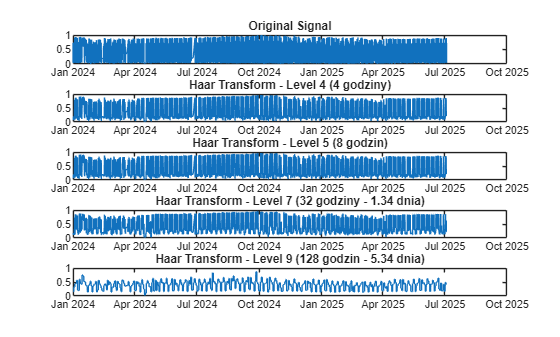

 
% Create a 4x1 subplot layout
subplot(5, 1, 1);
plot(ab_diff_train.Time, ab_diff_train_norm);
title('Original Signal');

subplot(5, 1, 2); % Specify the second subplot
plot(ab_diff_train.Time, HaarResults{1}); % Plot Haar_4
title('Haar Transform - Level 4 (4 godziny)');

subplot(5, 1, 3); % Specify the second subplot
plot(ab_diff_train.Time, HaarResults{1}); % Plot Haar_5
title('Haar Transform - Level 5 (8 godzin)');

subplot(5, 1, 4); % Specify the third subplot
plot(ab_diff_train.Time, HaarResults{2}); % Plot Haar_7
title('Haar Transform - Level 7 (32 godziny - 1.34 dnia)');

subplot(5, 1, 5); % Specify the fourth subplot
plot(ab_diff_train.Time, HaarResults{3}); % Plot Haar_9
title('Haar Transform - Level 9 (128 godzin - 5.34 dnia)');

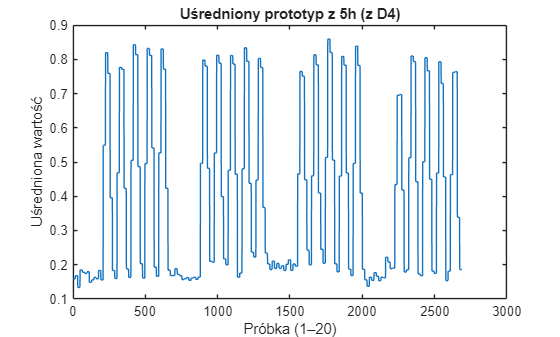

% --- Prototyp 5h z poziomu D4---
P_5h = 96*7*4;

signal_5h = Haar_4;
num_periods_5h = floor(length(signal_5h) / P_5h);
signal_5h_trimmed = signal_5h(1 : num_periods_5h * P_5h);

matrix_5h = reshape(signal_5h_trimmed, P_5h, num_periods_5h);
prototyp_5h = mean(matrix_5h, 2);

figure;
plot(prototyp_5h);
title('Uśredniony prototyp z 5h (z D4)');
xlabel('Próbka (1–20)');
ylabel('Uśredniona wartość');

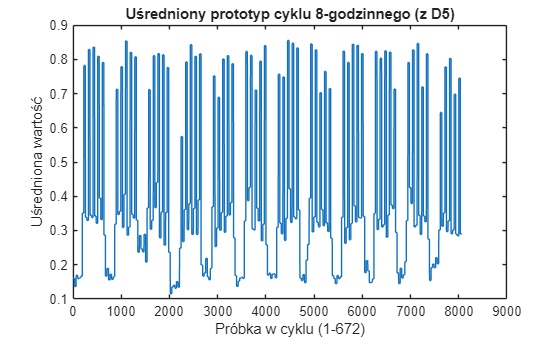

% --- Prototyp 8h z poziomu D5---
P_8h = 96 * 7* 4 * 3;
signal_8h = Haar_5;

% 2. Przytnij sygnał, aby był wielokrotnością okresu
num_periods_8h = floor(length(signal_8h) / P_8h);
signal_8h_trimmed = signal_8h(1 : num_periods_8h * P_8h);

% 3. Przekształć na macierz (każda kolumna to jeden cykl)
matrix_8h = reshape(signal_8h_trimmed, P_8h, num_periods_8h);

% 4. Oblicz średni cykl (uśrednij wzdłuż wierszy)
prototyp_8h = mean(matrix_8h, 2);

% 5. Wizualizacja
figure;
plot(prototyp_8h);
title('Uśredniony prototyp cyklu 8-godzinnego (z D5)');
xlabel('Próbka w cyklu (1-672)');
ylabel('Uśredniona wartość');

% --- Prototyp 24h z poziomu D7---
P_24h = 96*7*4;
signal_24h = Haar_7

signal_24h =     0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621
    0.1621


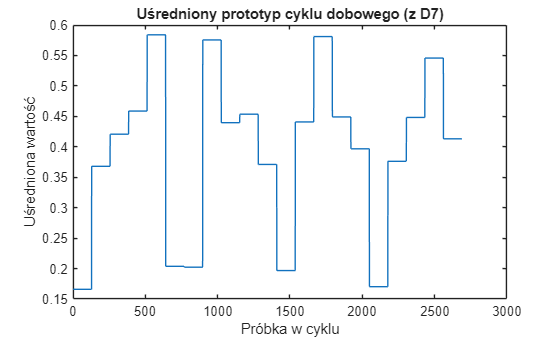


% 2. Przytnij sygnał
num_periods_24h = floor(length(signal_24h) / P_24h);
signal_24h_trimmed = signal_24h(1 : num_periods_24h * P_24h);

% 3. Przekształć na macierz
matrix_24h = reshape(signal_24h_trimmed, P_24h, num_periods_24h);

% 4. Oblicz średni cykl
prototyp_24h = mean(matrix_24h, 2);

% 5. Wizualizacja
figure;
plot(prototyp_24h);
title('Uśredniony prototyp cyklu dobowego (z D7)');
xlabel('Próbka w cyklu');
ylabel('Uśredniona wartość');

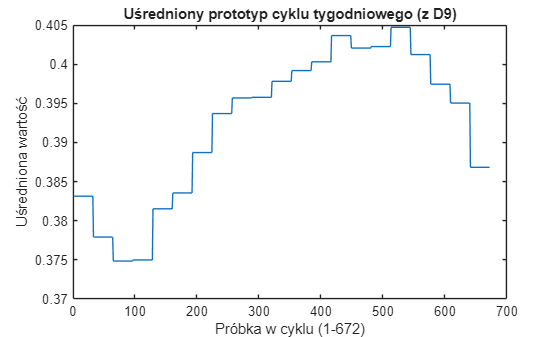

% --- Prototyp 7 dni z poziomu D9---
P_tydzien = 96 * 7;
signal_tydzien = Haar_9;

% 2. Przytnij sygnał
num_periods_tydzien = floor(length(signal_tydzien) / P_tydzien);
signal_tydzien_trimmed = signal_tydzien(1 : num_periods_tydzien * P_tydzien);

% 3. Przekształć na macierz
matrix_tydzien = reshape(signal_tydzien_trimmed, P_tydzien, num_periods_tydzien);

% 4. Oblicz średni cykl
prototyp_tydzien = mean(matrix_tydzien, 2);

% 5. Wizualizacja
figure;
plot(prototyp_tydzien);
title('Uśredniony prototyp cyklu tygodniowego (z D9)');
xlabel('Próbka w cyklu (1-672)');
ylabel('Uśredniona wartość');

dlugosc_treningu = length(ab_diff_train.Var1);
%dlugosc_testu = length(ab_diff_test.Var1);
dlugosc_testu = 2880;
dlugosc_calosci = dlugosc_treningu + dlugosc_testu;

% Zbuduj model 4h
model_5h = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_5h(i) = funkcja_sezonowa(i, prototyp_5h * 1);
end
model_5h_centered = model_5h - mean(model_5h);

rmse_5h = rmse(model_5h(1:dlugosc_treningu,:), Haar_4)

rmse_5h = 0.1342

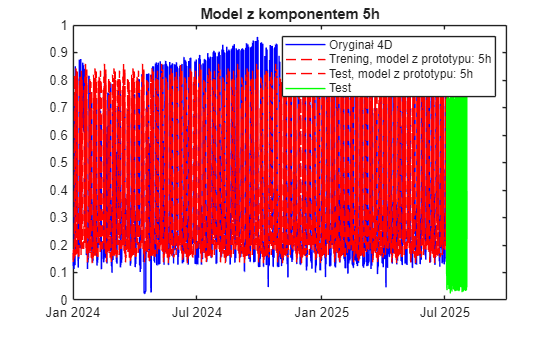


% Wizualizacja
figure;
plot(ab_diff_train.Time, Haar_5, 'b', 'DisplayName', 'Oryginał 4D');
hold on;
plot(ab_diff_train.Time, model_5h(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 5h');
plot(ab_diff_test.Time(1:dlugosc_testu), model_5h(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 5h');
plot(ab_diff_test.Time(1:dlugosc_testu), ab_diff_test_norm(1:dlugosc_testu), 'g', 'DisplayName', 'Test');

legend;
title('Model z komponentem 5h');

% Zbuduj model 8h
model_8h = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_8h(i) = funkcja_sezonowa(i, prototyp_8h);
end
model_8h_centered = model_8h - mean(model_8h);

rmse_8h = rmse(model_8h(1:dlugosc_treningu,:), Haar_5)

rmse_8h = 0.1102

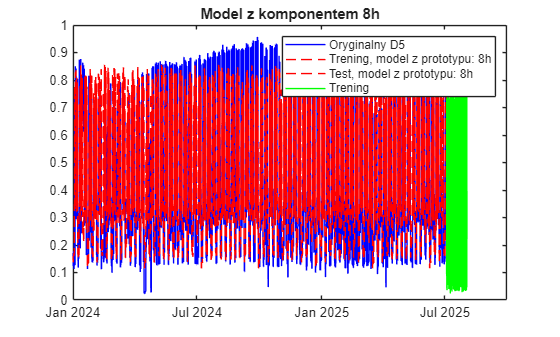


% Wizualizacja
figure;
plot(ab_diff_train.Time, Haar_5, 'b', 'DisplayName', 'Oryginalny D5');
hold on;
plot(ab_diff_train.Time, model_8h(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 8h');
plot(ab_diff_test.Time(1:dlugosc_testu), model_8h(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 8h');
plot(ab_diff_test.Time(1:dlugosc_testu), ab_diff_test_norm(1:dlugosc_testu), 'g', 'DisplayName', 'Trening');


legend;
title('Model z komponentem 8h');

% Zbuduj model 24h
model_24h = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_24h(i) = funkcja_sezonowa(i, prototyp_24h);
end
model_24h_centered = model_24h - mean(model_24h);

rmse_24h = rmse(model_24h(1:dlugosc_treningu,:), Haar_7)

rmse_24h = 0.0802

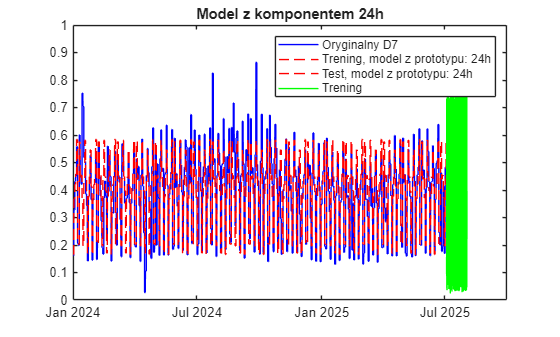


% Porównaj zrekonstruowany model z sygnałem D7
figure;
plot(ab_diff_train.Time, Haar_7, 'b', 'DisplayName', 'Oryginalny D7');
hold on;
plot(ab_diff_train.Time, model_24h(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 24h');
plot(ab_diff_test.Time(1:dlugosc_testu), model_24h(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 24h');
plot(ab_diff_test.Time(1:dlugosc_testu), ab_diff_test_norm(1:dlugosc_testu), 'g', 'DisplayName', 'Trening');


legend;
title('Model z komponentem 24h');

% Zbuduj model 7 dni
model_7d = zeros(dlugosc_calosci, 1);
for i = 1:dlugosc_calosci
    model_7d(i) = funkcja_sezonowa(i, prototyp_tydzien);
end
model_7d_centered = model_7d - mean(model_7d);

rmse_7d = rmse(model_7d(1:dlugosc_treningu,:), Haar_7)

rmse_7d = 0.1467

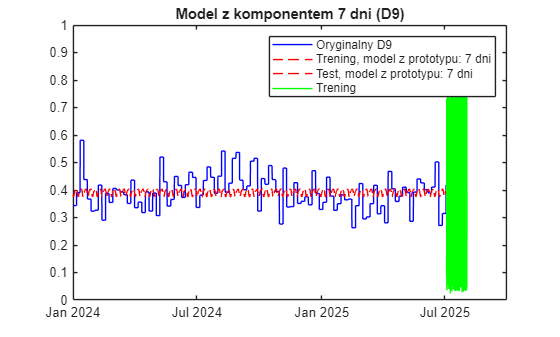


% Porównaj zrekonstruowany model z sygnałem D9
figure;
plot(ab_diff_train.Time, Haar_9, 'b', 'DisplayName', 'Oryginalny D9');
hold on;
plot(ab_diff_train.Time, model_7d(1:dlugosc_treningu,:), 'r--', 'DisplayName', 'Trening, model z prototypu: 7 dni');
plot(ab_diff_test.Time(1:dlugosc_testu), model_7d(dlugosc_treningu+1:end,:), 'r--', 'DisplayName', 'Test, model z prototypu: 7 dni');
plot(ab_diff_test.Time(1:dlugosc_testu), ab_diff_test_norm(1:dlugosc_testu), 'g', 'DisplayName', 'Trening');
legend;
title('Model z komponentem 7 dni (D9)');

trend_MA_original = movmean(ab_diff_train_norm,672*4);

sum_of_4_signals_train =  model_5h_centered(1:dlugosc_treningu,:)  + model_24h_centered(1:dlugosc_treningu,:) + model_7d_centered(1:dlugosc_treningu,:) + trend_MA_original;
rmse_sum_of_4_signals = rmse(sum_of_4_signals_train, ab_diff_train_norm);

trend_MA_original_test = movmean(ab_diff_test_norm,672*4);
sum_of_4_signals_test = model_5h_centered(dlugosc_treningu+1:end,:)  + model_24h_centered(dlugosc_treningu+1:end,:) + model_7d_centered(dlugosc_treningu+1:end,:) + trend_MA_original_test(1:dlugosc_testu);
%sum_of_4_signals_test =  model_8h_centered(dlugosc_treningu+1:end,:) +
%model_5h_centered(dlugosc_treningu+1:end,:)  +  model_7d_centered(dlugosc_treningu+1:end,:) +  trend_MA_original_test;

mae_sum_of_4_signals_test = mae(sum_of_4_signals_test, ab_diff_test_norm(1:dlugosc_testu))

mae_sum_of_4_signals_test = 0.2134

mape_sum_of_4_signals_test = mape(sum_of_4_signals_test, ab_diff_test_norm(1:dlugosc_testu))

mape_sum_of_4_signals_test = 200.4005

rmse_sum_of_4_signals_test = rmse(sum_of_4_signals_test, ab_diff_test_norm(1:dlugosc_testu))

rmse_sum_of_4_signals_test = 0.2837

r2_sum_of_4_signals_test = rmse(sum_of_4_signals_test, ab_diff_test_norm(1:dlugosc_testu))

r2_sum_of_4_signals_test = 0.2837

r_squared_of_4_signals_test = calculate_r_squared(sum_of_4_signals_test, ab_diff_test_norm(1:dlugosc_testu))

r_squared_of_4_signals_test = 0.3284

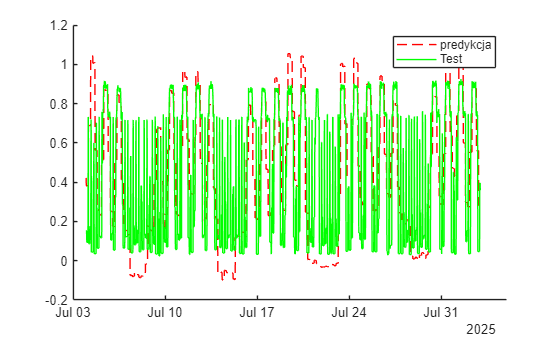


% Porównaj zrekonstruowany model
figure;
hold on;
%plot(ab_diff_train.Time, sum_of_4_signals_train, 'r--', 'DisplayName', 'Trening, Predykcja');
%plot(ab_diff_train.Time, ab_diff_train_norm, 'b', 'DisplayName', 'Trening');
plot(ab_diff_test.Time(1:dlugosc_testu), sum_of_4_signals_test, 'r--', 'DisplayName', 'predykcja');
plot(ab_diff_test.Time(1:dlugosc_testu), ab_diff_test_norm(1:dlugosc_testu), 'g', 'DisplayName', 'Test');
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu), ...
                   ab_diff_test_norm(1:dlugosc_testu), ...
                   sum_of_4_signals_test, ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_RECZ_month.xlsx');